# **Pràctica 5: Disseny de controladors en camp freqüencial**

Les pràctiques de l’assignatura control amb computador consisteixen en l’estudi d’un servomecanisme de posicionament angular controlat per un PC. Les sessions de laboratori P1 i P2 es centren, respectivament, en l’anàlisi experimental de les respostes temporal i freqüencial del sistema. Les sessions P3 i P4 es dediquen al disseny de controladors PID. Finalment, en la pràctica P5 es dissenyaran controladors en camp freqüencial.

**OBJECTIU: Disseny d'un controlador en el domini freqüencial de la posició de sortida per a la planta estudiada en les sessions anteriors per tal que el sistema en llaç tancat compleixi unes certes especificacions en el domini freqüencial.**

**En aquesta sessió l'estudiant ha de:**

- **Dissenyar un controlador per avanç de fase.**

- **Verificar experimentalment el sistema de control dissenyat.**

% Canvi entre les dades de l'experiment i els del directori Resultats
% Si voleu utilitzar les dades del directori Resultats = false
% Si voleu utilitzar dades pròpies = true
useExperimentalData = false;

# Introducció

En aquesta pràctica es presenten els controladors d'avanç i retard de fase. Aquestes controladors es posen es sèrie (cascada) amb la planta a controlar i tenen com a objectiu modificar el comportament del sistema en llaç tancat. El sistema de control ha de satisfer certes especificacions definides en el domini freqüencial mitjançant un marge de guany i/o un marge de fase. Pel disseny de controladors en el domini freqüencial, els sistemes de temps discret es transformen en sistemes similars de temps continu i s'antitransforma per tenir el controlador digital. A continuació es detalla la metodologia per al disseny de controladors d'avanç o retard de fase per a sistemes de temps continu; després es plantegen quatre exercicis.

La funció de transferència en *s* d'un controlador d'avanç o retard de fase genèric ve donada per


$$G_c \left(s\right)=K\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}$$


La relació $\alpha =\frac{\omega_p }{\omega_z }$ pel cas $\omega_p >\omega_z$, o $\alpha =\frac{\omega_z }{\omega_p }$ pel cas $\omega_p <\omega_z$ s'anomena longitud del controlador.

**CONTROLADORS D'AVANÇ DE FASE**

Corresponen al cas en que $\omega_z <\omega_p$  i serveixen per a millorar la resposta transitòria. En un cert interval de freqüències, incrementen (*avancen*) la fase del sistema controlat. El següent procediment permet determinar quant s’ha d'incrementar la fase i a quina freqüència s'ha de centrar l'acció del controlador.

Les equacions que s'han de verificar per tal que $\Phi_{\mathrm{md}}$ sigui el marge de fase del sistema realimentat són:


$$\begin{array}{l}
|G_c \left(j\;\omega_c \right)||\mathrm{GH}\left(j\;\omega_c \right)|=1\\
180+\mathrm{arg}\left(G_c \left(j\;\omega_c \right)\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\gamma_d 
\end{array}$$


Prenent $\omega_c =\sqrt{\omega_z \omega_p }=\omega_z \sqrt{\alpha }$ es poden escriure com


$$\begin{array}{l}
|G_c \left(j\;\omega_z \sqrt{\alpha }\right)||\mathrm{GH}\left(j\;\omega_z \sqrt{\alpha }\right)|=1\\
180+\mathrm{arg}\left(\frac{\alpha -1}{2\sqrt{\alpha }}\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_z \sqrt{\alpha }\right)\right)=\Phi_{\mathrm{md}} 
\end{array}$$


El disseny del controlador es realitza buscant una solució aproximada del sistema d'equacions anterior i comprovant finalment que el sistema en llaç tancat satisfà les especificacions. És un mètode de solució per prova i error. La solució aproximada s’obté resolent:


$$\begin{array}{l}
\theta_c =\Phi_{\mathrm{md}} +\Delta -\Phi_{\mathrm{GH}} \\
\alpha =\frac{1+\mathrm{sin}\;\theta_c }{1-\mathrm{sin}\;\theta_c }\\
|\mathrm{GH}\left(j\;\omega_c \right)|=\frac{1}{\sqrt{\alpha }}
\end{array}$$


on $\Phi_{\mathrm{GH}}$ és el marge de fase del sistema en llaç obert multiplicant pel guany estacionari del controlador i $\Delta$ és un marge addicional de seguretat que s'introdueix atès que es resol un sistema d'equacions aproximat enlloc del sistema exacte. La solució proporciona el màxim avanç de fase proporcionat pel controlador, $\theta_c$, la longitud del controlador $\alpha$ i la freqüència central $\omega_c$.

Les pulsacions $\omega_z$ i $\omega_p$ s'obtenen de $\alpha$ i $\omega_c$.


$$\omega_z =\frac{\omega_c }{\sqrt{\alpha }},\;\;\;\;\;\omega_p =\omega_c \sqrt{\alpha }=\omega_z \alpha$$


COMENTARIS:

En cas d'obtenir $\theta_c >60$ es pren $k$ de manera que $\frac{\theta_c }{k}<60$, es dissenya el controlador amb $\frac{\theta_c }{k}$ i s'aplica


$$G_c ={\left(\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}\right)}^k$$


Prèviament l'equació anterior s'haurà de reescrit com


$$|\mathrm{GH}\left(j\;\omega_c \right)|=\frac{1}{{\left(\sqrt{\alpha }\right)}^k }$$


**CONTROLADORS DE RETARD DE FASE**

En aquest cas $\omega_p <\omega_z$ i serveixen per a millorar precisió en estat estacionari. El qualificatiu de retard de fase prové de que, en un cert interval de freqüències, el controlador decrementa (*retarda*) la fase del sistema controlat. Com en el cas anterior les equacions que ha de satisfer el sistema controlat són:


$$\begin{array}{l}
|G_c \left(j\;\omega_c \right)||\mathrm{GH}\left(j\;\omega_c \right)|=1\\
180+\mathrm{arg}\left(G_c \left(j\;\omega_c \right)\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\gamma_d 
\end{array}$$


En aquest cas es determina la freqüència $\omega_c$ que proporcionaria el marge de fase desitjat del sistema de control i es calcula $\alpha$ de manera que $\omega_c$ sigui la freqüència de tall a 0dB d'aquest sistema. El controlador es centra suficientment a l'esquerra de $\omega_c$ per tal que el seu efecte sigui inapreciable en la fase de $|G_c \mathrm{GH}\left(j\;\omega_c \right)|$. Com en el cas dels controladors per avanç de fase, el procediment no és exacte sinó aproximat, raó per la qual cal introduir un marge addicional de seguretat i fer una comprovació al final.

Les variables $\theta_c ,\omega_c$ i $\alpha$ s'obtenen resolent les equacions:


$$\begin{array}{l}
\theta_c =\gamma_d +\Delta -180\\
\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\theta_c \\
\alpha =|\mathrm{GH}\left(j\;\omega_c \right)|
\end{array}$$


Finalment,


$$\omega_z =\frac{\omega_c }{10},\;\;\omega_p =\frac{\omega_z }{\alpha }$$


COMENTARIS:

- L'algorisme només es pot aplicar si l'equació $\arg \left(\textrm{GH}\left(j\;\omega_c \right)\right)=\theta_c$ té solució.

- En el cas que $\alpha >12$ es dissenya amb $\alpha^{\wedge } =\sqrt[k]{\alpha }$ per a $k$ natural suficientment gran i s'aplica


$$G_c ={\left(\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}\right)}^k$$


# Exercici 16: Determinació dels marges de guany i de fase del sistema.

Considereu la planta del laboratori amb sortida posició. Utilitzant MATLAB, comproveu que els marges de guany i de fase del sistema digital i del sistema equivalent que resulta d'aplicar la transformació bilineal coincideixen.

% Paràmetres de la planta
Kpot=1.62;
N=9;
K0=0.82/0.017;
tau0=0.26;
planta=tf([Kpot*K0/N],[tau0,1,0])


planta =
 
     8.682
  ------------
  0.26 s^2 + s
 
Continuous-time transfer function.



% Model de Temps discret
Ts=0.01;
plantad=c2d(planta,Ts,'zoh') ;

% Transformada Bilineal
plantaw=d2c(plantad,'tustin') ;

% Comprovació de la coincidència en el càlcul dels marges
display('Marges de la planta bilineal')

Marges de la planta bilineal


[Gmw,Pmw,Wcgw,Wcpw]=margin(plantaw)

Gmw = 23.1838

Pmw = 35.1259

Wcgw = 27.8243

Wcpw = 5.1783

display('Marges de la planta discreta')

Marges de la planta discreta


[Gmd,Pmd,Wcgd,Wcpd]=margin (plantad)

Gmd = 23.1858

Pmd = 35.1258

Wcgd = 27.6481

Wcpd = 5.1772

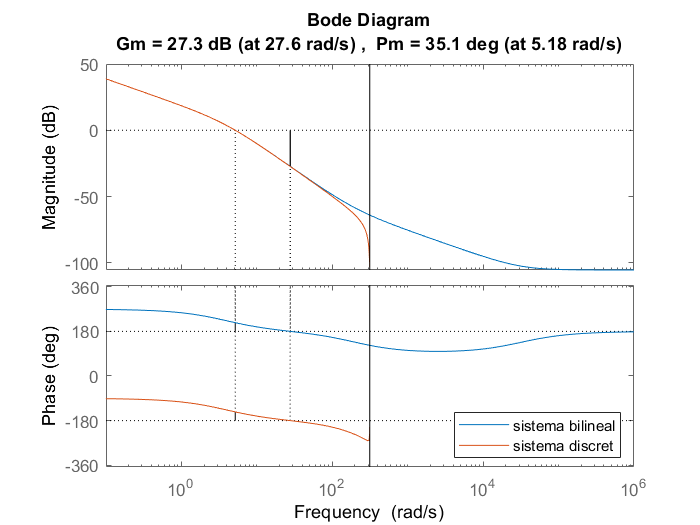

margin(plantaw)
hold on
margin(plantad)
legend('sistema bilineal','sistema discret','Location', 'SouthEast')

Com es pot observar, els marges obtinguts mitjançant la comanda *margin() *dels dos sistemes a analitzar, són exactament els mateixos.

# Exercici 17: Disseny d'un controlador d'avanç de fase.

Amb l'ajuda de MATLAB, dissenyeu un controlador d'avanç de fase que faci que el sistema de llaç tancat, per al control de posició de la planta del laboratori, amb un període de mostratge Ts=0.01s, tingui un marge de fase de 45º i error estàtic amb una entrada en rampa del 10%. Considereu un marge de fase addicional de seguretat de $\Delta =15º$.

% Paràmetres de la planta
Kpot=1.62;
N=9;
K0=0.82/0.017;
tau0=0.26;
planta=tf([Kpot*K0/N],[tau0,1,0])


planta =
 
     8.682
  ------------
  0.26 s^2 + s
 
Continuous-time transfer function.



% Model de Temps discret
Ts=0.01;
plantad=c2d(planta,Ts,'zoh') ;

% Transformada Bilineal
plantaw=d2c(plantad,'tustin') ;

% Càlcul del guany necessària
% Coeficient d'error de velocitat
errordes=0.1;
Kv=(1/errordes);

% Càlcul de l'increment de guany necessària
% (Guany del controlador)
Kvplanta=Kpot*K0/N;
Kcontrolador=Kv/Kvplanta

Kcontrolador = 1.1518

% Càlcul del marge de Fase
[Gm,Pm,Wcg,Wcp]=margin(Kcontrolador*plantaw)

Gm = 20.1290

Pm = 32.6959

Wcg = 27.8243

Wcp = 5.6375

% Càlcul de la Fase que ha de afegir el controlador
gamma=45;
delta=15;
theta=(gamma+delta-Pm)*pi/180;

% Càlcul del paràmetre alpha
alpha=(1+sin(theta))/(1-sin(theta));

% Recerca del punt on el sistema té el guany 1/sqrt(alpha)
[aux1,aux2,aux3,wc]=margin(Kcontrolador*plantaw*sqrt(alpha));
wc

wc = 7.4975

% Col·loquem el pol i el zero
wz=wc/sqrt(alpha); %Avanç
wp=wz*alpha ;

% Construcció del controlador
Gcw=tf([1/wz,1],[1/wp,1]);

% Bilineal Inversa: Obtenció del Controlador
Gcz=c2d(Gcw,Ts,'tustin')


Gcz =
 
  2.597 z - 2.481
  ---------------
    z - 0.8841
 
Sample time: 0.01 seconds
Discrete-time transfer function.



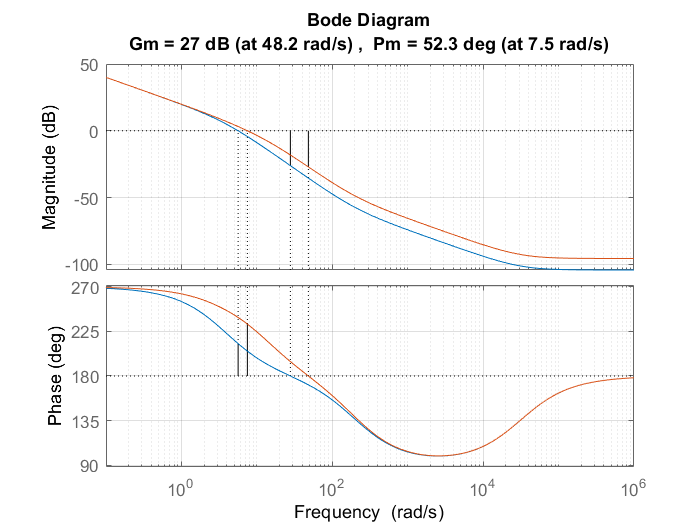

% Resposta freqüencial en llaç obert
% (Verificació del compliment de les especificacions)
figure
Gczplantad=series(Kcontrolador*Gcz,plantad);
Gczplantaw=d2c(Gczplantad,'tustin');
margin(Kcontrolador*plantaw)
hold on


margin(Gczplantaw)
grid

disp('mireu si us agrada el nou marge de fase ; premi qualsevol tecla')

mireu si us agrada el nou marge de fase ; premi qualsevol tecla


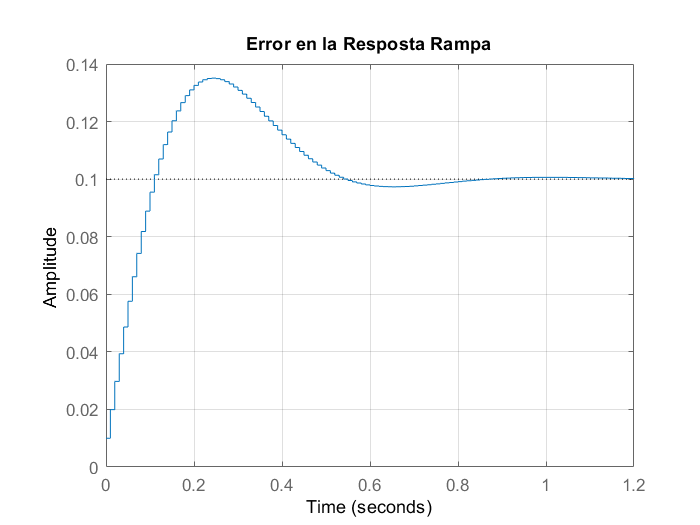

pause

% Construcció del Sistema en llaç tancat
closed=feedback(Gczplantad,1);
err=1-closed;

% Verificació de la resposta temporal
figure
grao=tf([1 0],[1,-1],Ts);
step(minreal(err*grao)*Ts ) ;
grid
title('Error en la Resposta Rampa')

% Preparació de dades per a Simulink 

disp('coeficients de la funció de transferència del controlador de guany unitària en z')

coeficients de la funció de transferència del controlador de guany unitària en z


Kc=dcgain(Gcz)

Kc = 1

Zc=zero(Gcz)

Zc = 0.9553

Pc=pole(Gcz)

Pc = 0.8841

# Exercici 18: Anàlisi en simulació.

- Compareu els diagrames de bode del sistema en llaç obert amb el controlador dissenyat afegint-li retards d'un, dos, tres ... períodes de mostratge. 

- Quants períodes de retard pot aguantar el sistema mantenint l'estabilitat? 

Executeu el model P5_Ex19.slx, definiu els paràmetres del controlador dissenyat. Visualitzeu la resposta temporal del sistema amb i sense retards afegits.

- Relacioneu el comportament del sistema controlat amb el marge de fase observar en els diagrames de bode.

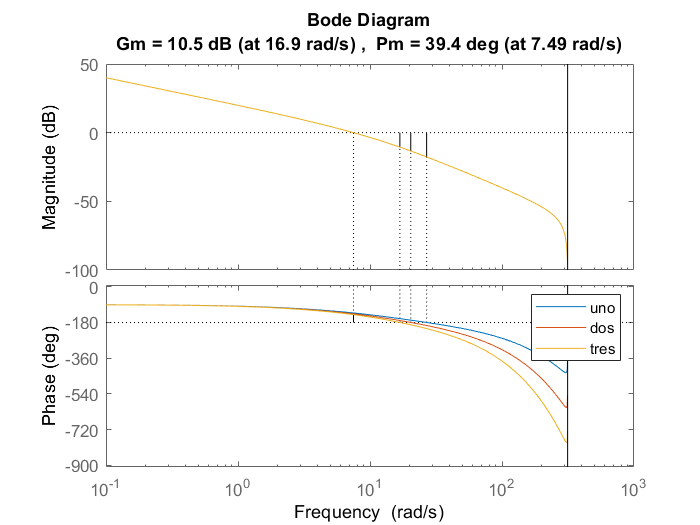

% Generació dels retards
unret=tf([1],[1 0],Ts) ;
dosret=tf([1],[1 0 0],Ts) ;
tresret=tf([1],[1 0 0 0],Ts) ;

% Visualització dels diferents diagrames de Bode
figure
margin(unret*Gcz*plantad*Kcontrolador)
hold all
margin(dosret*Gcz*plantad*Kcontrolador)
margin(tresret*Gcz*plantad*Kcontrolador)
legend('uno','dos','tres')

Creant més retards, podrem observar com a partir de retards de 13 períodes de mostreig el sistema es torna inestable. D'altra banda, simulant el model P5_Ex19.slx podem observar com en la resposta a una entrada tipus rampa obtenim un error de 0,01.

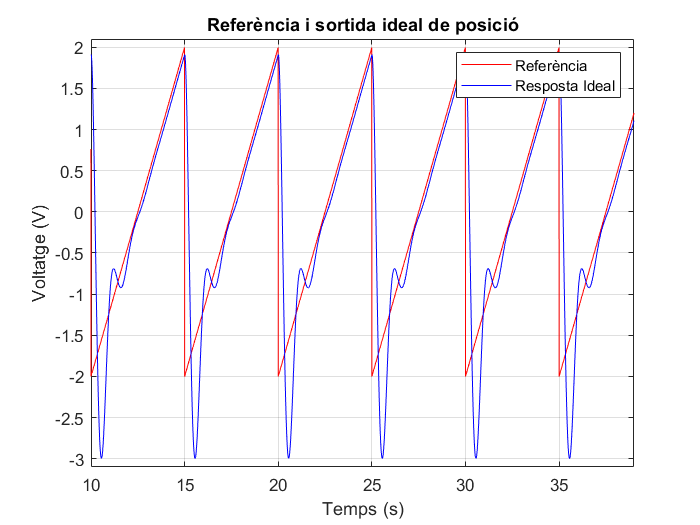

if useExperimentalData
    % Utilitzar Simulink
    open P5_Ex19.slx
    run P5_Ex19.slx;
else
    FileName   = 'P5_real_ideal.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac5'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,2,:)],'r')
hold on; grid on;
plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,3,:)],'b')
xlim([10 39]); ylim([-3.1 2.1]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Referència i sortida ideal de posició');
legend('Referència','Resposta Ideal');

# Ejercicio 19: Implementació del controlador d'avanç de fase.

Executeu el model P5_Ex20.slx i visualitzeu el comportament del sistema de control experimental i comproveu l'especificació relativa a la constant de velocitat.

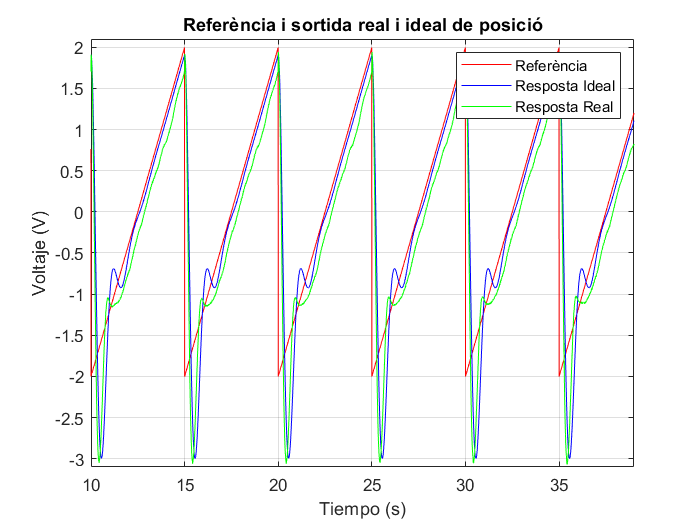

if useExperimentalData
    % Utilitzar Simulink
    open P5_Ex19.slx
    run P5_Ex19.slx;
else
    figure
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,2,:)],'r')
    hold on; grid on;
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,3,:)],'b')
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,1,:)],'g')
    xlim([10 39]); ylim([-3.1 2.1]);
    xlabel('Tiempo (s)');
    ylabel('Voltaje (V)');
    title('Referència i sortida real i ideal de posició');
    legend('Referència','Resposta Ideal','Resposta Real');
end

Com es pot observar, la sortida real té un error constant enfront d'una entrada tipus rampa, però la dinàmica de la sortida no és el mateix que l'ideal, aquesta diferència prové de les dinàmiques no modelades del sistema. 